Function calls to develop working understanding

%differences between 16 and 64 @ sigma 0.1
[error16, error16ofdm] = qam_OFDM_fadechannel_func(16,16,4,0.1);
[error64, error64ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.1);

%differences between different values of sigma at 64 SC
sumError = 0; 
tic
for n=1:1000
    for i=1:10
        [error(i,:,n), errorOfdm(i,:,n)] = qam_OFDM_fadechannel_func(16,64, 0, 0.1*i);
        [~, errorOfdm16(i,:,n)] = qam_OFDM_fadechannel_func(16,16, 0, 0.1*i);
    end  
end
toc

Elapsed time is 237.112093 seconds.


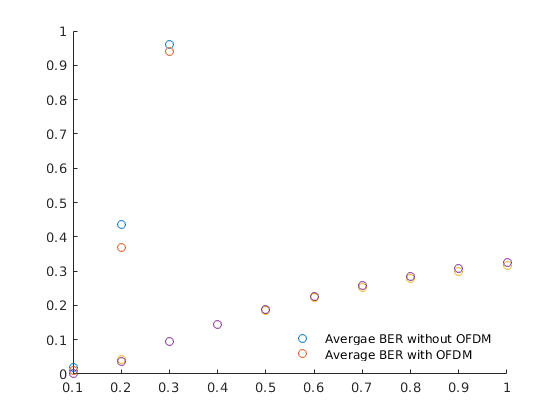


x1 = [0.1:0.1:1];
x2 = [0.1 0.2 0.3];
avgerror = sum(error,3);
avgerrorOfdm = sum(errorOfdm,3);
avgerrorOfdm16 = sum(errorOfdm16,3);
avgError = avgerror(:,1)/1000;
avgErrorOfdm = avgerrorOfdm(:,1)/1000;
avgErrorOfdm16 = avgerrorOfdm16(:,1)/1000;
scatter(x1,avgError)
hold on
scatter(x1, avgErrorOfdm)
legend('Avergae BER without OFDM','Average BER with OFDM','Location','southeast')
legend("boxoff")
hold off

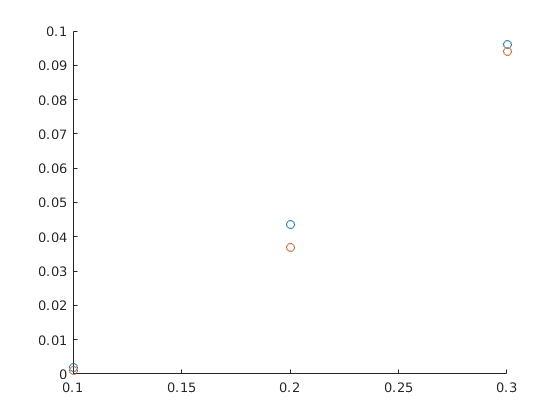

figure
scatter(x2, avgError(1:3))
hold on
scatter(x2, avgErrorOfdm(1:3))

% [error1, error1ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.1);
% [error2, error2ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.2);
% [error3, error3ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.3);
% [error4, error4ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.4);
% [error5, error5ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.5);
% [error6, error6ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.6);
% [error7, error7ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.7);
% [error8, error8ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.8);
% [error9, error9ofdm] = qam_OFDM_fadechannel_func(16,64,16,0.9);
% [error10, error10ofdm] = qam_OFDM_fadechannel_func(16,64,16,1);

x = [0:0.05:1];
